# Man On The Moon

[⇦ Overview](matlab:open('./Overview.html'))

Conservation of Mass and Momentum are the fundamental equation of fluid dynamics. This script investigates their application to the modeling of the launch of one of the most famous space exploration missions, comparing the results to the actual flight log from the mission.

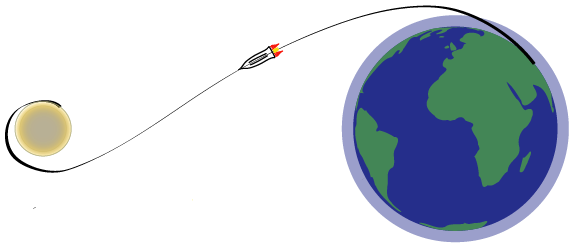

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

From 1961 to 1972, NASA pursued the Apollo space exploration program. Named after the Greek god of the sun, the program’s principal objective was to establish the first human presence on the Moon. On July 16th, 1969, the Apollo 11 mission launched from Cape Canaveral, Florida. The mission Commander, Neil Armstrong, would become the first astronaut to set foot on the Moon. In this script, we will use the mass and momentum conservation equations to study the first phase of this mission’s launch.

The rocket used to send the small, crewed spacecraft into Earth orbit, and later on the way to the Moon, was the Saturn V. Until November 2022, this rocket was the most powerful to launch a space exploration mission. The rocket launch sequence is divided into multiple phase, in this script we will focus on the study of the first phase. 

In this script, we are using the integral form of the mass and momentum conservation equation to predict the altitude with respect to time during the first phase of the launch. The known parameters of the problem are the initial mass of the rocket $m_0$, the rocket specific impulse $I_{sp}$, the rocket burn time $t_{s1}$ and the mass of propellant $m_p$. The specific impulse of the rocket is a measure of the efficiency of the rocket engine and can be used to estimate the propellant velocity at the exhaust of the rocket engine using the following relation:


$$u_e = g I_{sp}$$


where $u_e$ represents the exhaust velocity and $g$ is the gravity. The exhaust velocity is considered to be constant during the first phase of the ascent.

  **Try**. To understand the sheer size of the Saturn V rocket, click the following button to compare its size to a football field at the same scale.

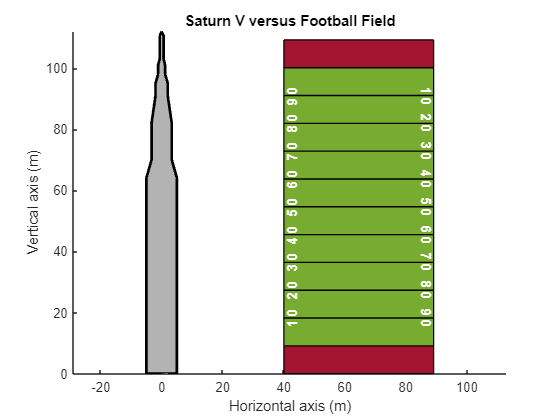

 
figure
DrawSaturn(DrawFootball=true);
title("Saturn V versus Football Field")

## Control Volume and Control Surfaces 

 **Definition. **In continuum mechanics and so in fluid mechanics, the control volume method allows to solve the integral form of conservation equation (e.g., mass, momentum and energy). While fluid are deformable and usually do not hold fixed shape, the control volume method allows to study to rate of change in mass, momentum and energy within a abstract volume in space.

**This calculation from this method allow quick study of the system, such as its change in mass, the forces action, the change in temperature, etc. **The first step of the control volume method consist in determining a judicious control volume to study the system.

  **Try**. We are proposing three different definitions of the Control Volume. Use the following drop-down to explore the proposed definitions.

figure
DrawSaturn(ControlVolume = 1);
title("Control Volume Proposed Definitions")

 **Exercise.** Which of the following control volumes seems to be the most adequate for this problem?

qControlVolumeDefinition("None")

The control volume being define, we can now break down its boundary into multiple control surfaces. This step is not always necessary but often simplify the computation.

  **Try**. Explore the definition of the control volume and control surfaces that will be used throughout this script.

DrawSaturn(Highlight="none");
title("Adopted Control Volume Definition")

As stated previously, the control volume method is used to solved the integral form of the conservation equations, which include the calculation of fluxes throught the control surfaces. This step is a common source of error, as it is easy to commit sign error in the dot product within the integral of the following form:


$$\int_{CS} (\vec{u}\cdot \vec{n})\phi \; dS$$
                 
$$(\star)$$


In $(\star)$, $\phi$ represent any physical quantity of interest, which could be the density $\rho$ for the mass conservation equation, or the momentum $\rho\vec{u}$ for the momentum conservation equation. The normal unit vector along the control surface is expressed by $\vec{n}$, and is defined so that the resulting flux is accounted posotively if it is leaving the control volume and negatively if it enters the control volume.

 **Exercise.** What is the direction of the normal unit vector to the bottom control surface to satisfy this convention?

qNormalBottomSurface("none")

  **Pro-tip**. Formally defining the normal unit vector of the control surfaces is not an optional steps, but it might help you aboid error signs later in the calculation. 

  **Try**. Use the following drop-down control to visualize the normal unit vector over each control surface.

LookAtNormalVector("none")

**Remark:** $\vec{n}$ represents the normal unit vector, therefore $||\vec{n}|| = 1$. On the previous figure and all following figure, the normal unit vector will not be represented up to scale.

**Remark: **note that the direction of the normal unit vector along the right and left control surface is not the same along the whole surface. This is because, unlike the bottom control surface, these surfaces are not defined by a straight line.

## Solve the Mass Conservation Equation

Now that the control volume, control surfaces and their normal unit vector are formally defined, we can apply the integral form of the conservation equations over the control volume. Prior to lift-off, most of the mass of the rocket is composed of the propellant itself. During the launch, the mass of the rocket will vary drastically. In order to study the variation of the mass of the rocket with time, we are applying the mass conservation equation to the control volume.

** Definition. **Integral Form of the Mass Conservation Equation


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$


f = figure;
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, ...
    WriteExhaustVelocity=true, DrawExhaustMassFlow=true, WriteExhaustMassFlow=true);
annotation('textarrow',Position=[0.7 0.35 0.1 0]);
annotation('textbox',Position=[0.8 0.3 0.2 0.1],String="$\vec{e_x}$",Interpreter="latex",...
    VerticalAlignment="middle",LineStyle="none");
annotation('textarrow',Position=[0.7 0.35 0 0.14]);
annotation('textbox',Position=[0.6 0.46 0.2 0.1],String="$\vec{e_y}$",Interpreter="latex",...
    LineStyle="none",HorizontalAlignment="center");
 

**Remark: **in the previous figure, we are defining the coordinates system that will be used in the rest of the script.

### **Simplifying Mass Conservation**

The first step of the calculation is to break the integral over the control surfaces that we defined previously.


$$\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = \\

\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho \; dV}_\text{A}
+
\underbrace{\int_{CS_{right}} (\vec{u}\cdot\vec{n})\rho \; dS }_\text{B}
+
\underbrace{\int_{CS_{left}} (\vec{u}\cdot\vec{n})\rho \; dS }_\text{C}
+
\underbrace{\int_{CS_{bottom}} (\vec{u}\cdot\vec{n})\rho\;  dS }_\text{D}
= 0$$
               
$$(\heartsuit)$$


The second step should be to simplify equation $(\heartsuit)$, by identifying the terms equal to zero.

 **Exercise.** In our case, identify the term equal to zero if any.

qNullTermMass(A = false, B = false, C = false, D = false);  

** Assumption. **The mass flux through the bottom control surface correspond the the amount of propellant leaving the rocket engines per unit of time, it is usually expressed in (kg/s). In our case, we are considering this mass flow to be constant during the first stage of the launch:


$$\dot{m}_e = m_p \;/ \;t_{p1}$$


### Calculation of Inertial Term

Now that the mass conservation equation $(\heartsuit)$ has been simplified as much as possible:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho \; dV}_\text{A}
+
\underbrace{\int_{CS_{bottom}} (\vec{u}\cdot\vec{n})\rho\;  dS }_\text{D}
= 0
\quad\quad(\heartsuit)$$


It is time to expressed our first integral, the inertial term of the mass conservation equation. This term correspond to variation of mass per unit of time and should be expressed in unit such as (kg/s).

 **Exercise.** What does term A in $(\heartsuit)$ can be expressed? where $m(t)$ correspond to the mass of the rocket with respect to time.


$$\text{A) } \frac{\partial m(t)}{\partial t} 
\quad\quad
\text{B) } {\bf u}\cdot \frac{\partial m(t)}{\partial t}
\quad \quad
\text{C) } u_e \frac{\partial m(t)}{\partial t}
\quad \quad
\text{D) } \frac{ \partial (t \; m(t) )}{\partial t}$$


qInertiaMass(0);

### Calculation of Mass Flux Term

The remaining integral term in the mass conservation equation $(\heartsuit)$ consists of the mass flux through the bottom control surface.


$$\int_{CS_{bottom}} (\vec{u}\cdot\vec{n})\rho \; dS 
$$


figure
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true);
title("Rocket bottom with velocity and normal unit vector")

 **Exercise. **Considering the direction of $\vec{n}$ and  $\vec{u}$; simplify $\vec{u} \cdot \vec{n}$,


$$\text{A) }\vec{u}\cdot\vec{n} = -u_e
\quad\quad
\text{B) }\vec{u}\cdot\vec{n} = u_e$$


qDotProductMass(0)

Now that the dot product is out of the way, it is time to integrate over the control surface.


$$\int_{CS_{bottom}} \rho u_e \; dS
$$


 **Exercise.** Express the result of the integral from the previous equation in term of $\dot{m}_e$.


$$\text{A) } \vec{u}\cdot\dot{m}_e
\quad\quad
\text{B) } -u_e\dot{m}_e
\quad\quad
\text{C) } \dot{m}_e
$$


qMassFlowTerm(0)

figure
DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true, ...
    DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);
title("Summary of Rocket's Mass Balance")

### Solve

The final form of the mass conservation equation $(\heartsuit)$ for this rocket model consists of the differential equation:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho \; dV}_\text{A}
+
\underbrace{\int_{CS_{bottom}} (\vec{u}\cdot\vec{n})\rho\;  dS }_\text{D}
= 0\\
\underbrace{\frac{\partial m(t)}{\partial t}}_\text{A}
+ 
\underbrace{\dot{m}_e}_\text{D}
 = 
0 \quad\quad (\heartsuit)$$


The mass conservation equation led to a first-order differential equation $\frac{\partial m(t)}{\partial t}  + \dot{m_e} = 0$, this equation is easy to solve anaticaly and have solution of the following form:


$$m(t) = -\dot{m}_e   t + C$$


The integration constant $C$ can be determined by considering the initial mass of the control volume, $m_0$.


$$m(0) = m_0 = -\dot{m}_e(0)+C$$



$$m(t) = m_0 - \dot{m}_e t$$
              

The initial mass of the Saturn V used in Apollo 11 was 2,950,000 kg. Out of this mass, around 70% (2,000,000 kg) was the mass of propellant $m_p$ burned during the first phase of the launch.

  **Try**. Considering the mass of propellant and the fact that it was entirely burnt during the first phase of the launch which lasted 161 seconds, set the mass flow its right value on the day of the launch to visualize the mass of the rocket with respect to time.

MassFlow = 15000;
SolveMassConservationEquation(MassFlow)

 **Reflect**. The amount of rocket fuel used during the first phase of the launch represents emptying 200 average car tanks every second during the 161 seconds of the first phase, for a total of almost 34,000 cars. 

**Remark.** Because the mass balance of this problem is relatively simple, one could have expressed the differential equation $(\heartsuit)$ without expressing the mass conservation equation. 

MassFlow = 2000000/161; % Fix the Mass Flow to the right value for the rest of the script

## Solve the Momentum Conservation Equation

In the previous section we solve that we solved the mass conservation equation and defined the mass of rocket with respect to time. In this section we will consider the conservation of momentum in order to define the altitude of the rocket with respect to time.

**  Definition. **Integral Form of the Momentum Conservation Equation


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


where $\rho$ is the density, $\vec{u}$is the velocity vector, the momentum is defined as $\rho\vec{u}$, and $\vec{F}$ are the external forces acting on the control volume. We are considering the same parameters than the previous section, and the results from the previous section:

$m(t) = m_0 - \dot{m}_e t$.

The initial mass of the rocket is defined $m_0 =$ 2,950,000 kg and $\dot{m}_e = m_p \;/\; t_{p1} =$ 12,400 (kg/s) dring the first phase of the launch. 

figure
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true,...
    WriteExhaustVelocity=true, DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);
title("Summary of Rocket's Mass Balance")

### **Simplifying Momentum Conservation**

Similarly to the step we followed to solved the mass conservation equation, the first step in solving the momentum conservation equation is to break down the integral over the control surface into the control surfaces that we define in the first section.


$$\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV
+
\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS
= 
\sum \vec{F}\\
\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV
+
\int_{CS_\text{right}}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS
+
\int_{CS_\text{left}}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS
+
\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS
= 
\sum \vec{F}\\
$$
       
$$(\spadesuit)$$


Again, the second step consist in identifying the fluxes that are equal to zero along the different surfaces.

 **Exercise**. Identify the fluxes equal to zero in the previous equation $(\spadesuit)$


$$A)\quad\displaystyle \int_{CS_{\text{right}}} (\vec{u} \cdot  \vec{n}) \rho \vec{u} \; dS$$
  


$$B)\quad \displaystyle \int_{CS_{\text{left}}} (\vec{u} \cdot  \vec{n}) \rho \vec{u} \; dS$$
   


$$C)\quad\displaystyle \int_{CS_{\text{bottom}}} (\vec{u} \cdot  \vec{n}) \rho \vec{u} \; dS$$


qNullTermMomentum(CSR = false,CSL = false,CSB = false); 

### Calculation of the Acceleration Term

Now that the momentum conservation equation are as simplify as possible we can start calculating each term one by one, starting with the cceleration term:


$$\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV$$


** Assumption. **The acceleration term is considered to be negligible compare to the other term in $(\spadesuit)$. This relies that the variation of momentum due to the displacement of mass is negligible compare to the thrust generated at the exhaust of the rocket's engine.

Thus, the equation $(\spadesuit)$ reduces to:


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS
= 
\sum\vec{F}\\
$$


### Projection over the Reference Frame

The mass conservation equation is a scalar conservation equation, while momentum is a vector quantity. Thus, we need to project the equation over the vector of our reference frame $(\vec{e_x},\vec{e_y})$.


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_x}) \; dS = \sum F_x \\
\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS = \sum F_y$$


** Assumption. **As a first approximation, we are considering that the flight trajectory of the rocket is directly vertical with no horizontal displacement. Therefore, the remaining equation is solely along the y-axis of the domain.


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS = \sum{F_y}
\quad\quad(\spadesuit)$$


### Thrust Term

Next, we are calculating the integral term corresponding to the thrust generated by the flow of propellant through the rocket's engine. In order to avoid sign error, we can predict the resulting sign from the integral. If the thrust is align with the reference frame unit vector $(\vec{e_y})$, than the result of the integral should be positive, otherwise is should be negative.

 **Exercise.** In the case of Saturn V, what should be the direction of the thrust force resulting from the mass flux through the rocket's engines?

qThrustDirection( "None")

 **Exercise.** What is the sign resulting from the two dot product in $\displaystyle \int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS 
=
\int_{CS_\text{bottom}} \pm u_e \rho u_e \; dS
$? Is it zero, positive or negative?

qThrustSign(0)

Remember that we are considering that the mass flow is constant and the exhaust velocity is defined from the rocket specific impulse during the first phase of the launch.

 **Exercise.** How can $\displaystyle \int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS$ be expressed in terms of $u_e$ and  $\dot{m}_e$?


$$\text{A) } u_e^2\dot{m}_e
\quad\quad
\text{B) } -u_e\dot{m}_e
\quad\quad
\text{C) } -\dot{m}_e
\quad\quad
\text{D) } -u_e^2$$


qThrustTerm("None")

### Forces term

The last term to defined in $(\spadesuit)$ is $\sum F_y$, in order to calculate this term we first need to think about what forces are even acting on the control volume?

 **Exercise.** In the case of Saturn V, what forces should be included?

qBodyForces( ...
    Gravity = false, ...
    Spring = false, ...
    Electric = false, ...
    Friction = false, ...
    Magnetic = false, ...
    Thrust = false, ...
    Acceleration = false); 

** Assumption.** For the moment, we will neglect the air resistance on the rocket's hull, and we will consider the gravity constant equal to the gravity at sea-level.

The different component of the force term $\sum F_y$ should be positive if their corresponding force are in the same direction as the reference vector $(\vec{e_y})$, negativeif in opposite direction. 

 **Exercise**. What is the correct expression for the gravitational forces acting on the rocket?


$$\text{A) } g\,m_0
\quad\quad
\text{B) } -g\,m_0 
\quad\quad
\text{C) } g \,\dot{m}_e
\quad\quad
\text{D) } -g\,m(t)$$


qGravityTerm(0)

The gravity being calculated, we are left with the acceleration term. We can think as this acceleration force felt by the control volume like the force acting on us in a plane at take-off. When the pilot push the jet engine at max thrust, we are feeling a resulting force pushing in the back of our seat.

 **Exercise**. What should be the direction of the resulting force from the acceleration of the control volume?

qAccelerationDirection("None")

 **Exercise**. How can you model the force due to the acceleration of the control volume? In this expression, $y_r$ represents the altitude of the control volume, it is attached to the bottom of the rocket so that $y_r(t=0) = 0$, the initial altitude of the rocket is 0.


$$\text{A) } m(t)\frac{d^2y_r}{dt^2}
\quad\quad
\text{B) } -m(t)\frac{d^2y_r}{dt^2}
\quad\quad
\text{C) } \dot{m}_e\frac{d^2y_r}{dt^2}
\quad\quad
\text{D) } -\dot{m}_e\frac{d^2y_r}{dt^2}$$


qAccelerationTerm(0)

### Solve

In the previous subsections we calculated the term resulting from the momentum conservation equation and found the following equation


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS = \sum\vec{F_y}
\quad\quad(\spadesuit) \\
-u_e\dot{m}_e = -m(t)\frac{d^2y_r}{dt^2}-m(t)g\\
\text{Thus, } \quad \frac{d^2 y_r}{dt^2}= \frac{u_e\dot{m}_e}{m(t)}-g$$


This latest equation was obtain by considering a constant mass flow and exhaust gas velocity at the rocket engine, neglecting the friction with surrounding air, having constant gravity and with Saturn V flight path being purely vertical. Remember that the mass conservation equation result defined the mass of the rocket with respect to time:


$$m(t) = m_0-\dot{m}_et$$


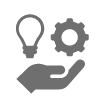**Computational Thinking.** While the resulting equation from the mass conservation equation was easy to solve analyticly, the second order differential equation arising from the momentum conservation equation is much more complex and would be nearl impossible to solve without some of the assumption we took earlier in this script. It is a perfect candidate for MATLAB's Ordinary Differential Equations solver. The following results from the differential equation were obtained using [`ode45`](https://www.mathworks.com/help/matlab/ref/ode45.html?searchHighlight=ode45&s_tid=srchtitle_ode45_1).

 
try
    SolveMomentum(MassFlow,false,true)
catch
    warning("MassFlow was not defined, current model is running with mass flow of 12,500 kg/s. "...
        + "Please, solve mass conservation equation to define MassFlow correctly.")
    MassFlow = 12500;
    SolveMomentum(MassFlow,false,true)
end

 **Reflect**. Calculation based on the mass conservation equation allowed us to define the mass of the rocket with respect to time, while the calulation from the momentum conservation equation gave us the altitude of the rocket with respect to time.

## Analysis of the model

The result from $(\spadesuit)$ are giving are general agreement with the flight data from Apollo 11 flight log. However, we are overestimating the altitude that the rocket reached by the end of the first phase of the flight.

 **Exercise. **Which one of the following statement could have cause the inaccuracy of the mathematical model that we develop in the previous section?

qSourceInaccuracy( ...
    BadPhysics = false, ...
    Friction = false, ...
    FlightPath = false, ...
    Gravity = false, ...
    Performance = false);  

In the remaining of the script we will be working on correcting some of this innacuracy. First we will take into consideration the variation of gravity with respect to the altitude, second we will take into consideration the flight path of the rocket.

### **Correction for Gravity**

The gravity felt by the rocket is function of the altitude according the the following relation:


$$g(y_r) = \frac{GM_t}{(r_t+y_r)^2}$$


Where $G$ is the gravitational constant, $M_e$ is the Earth mass ($5.97\times10^{24}$ kg), $r_e$ is the Earth radius ($6.371\times10^{6}$ m) and $y_r$ the altitude of the rocket as defined previously.


$$\frac{d^2 y_r}{dt^2}= \frac{u_e\dot{m}_e}{m(t)}-g(y_r)$$


The new differential equation is solved using the same method as the first model.

 
try
    SolveMomentum(MassFlow,true,false)
catch
    warning("MassFlow was not defined, current model is running with mass flow of 12,500 kg/s. "...
        + "Please, solve mass conservation equation to define MassFlow correctly.")
    MassFlow = 12500;
    SolveMomentum(MassFlow,true,false)
end

 **Reflect**. Becase gravity is decreasing with altitude, we should expect the rocket to reach a higher altitude by adding this variation in our model. However, the difference with the first results seems minor. In fact, variation of gravity have nearly no effect on the results during the first phase of the launch because is rocket "only" reach around 60 km altitude. Its effect would be much more important as altitude grows.

### Correction for rocket flight path angle

In the previous section, we consider that the trust of the rocket was directed verticaly and therefore the flight path of the rocket should be purely vertical. However, the flight path of Apollo 11 was not directed directly verticaly. The mission consisted a getting the spacecraft into earth orbit for a couple of revolution before the start the translunar injection.

 
figure
DrawSaturn(PathAngle=20);

Going back to the equation from mass conservation equation:


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_x}) \; dS = \sum F_x \\
\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS = \sum F_y$$


Even tough, we are no longer considering a purely vertical rocket path, we are only interested in the altitude of the rocket. Therfore our effort are only focusing on the second equation. Developping the y-component of the forces vector we obtain:


$$\int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS 
= 
-m(t)g(y_r)-m(t)\frac{d^2y_r}{dt^2}
$$


The right hand side of the equation is unchanged from the previous model, however the left-hand side should be different because the velocity vector $\vec{u}$ is no longer align with $\vec{e_y}$.

 **Exercise. **What is the result of the dot product $\vec{u}\cdot\vec{e_y}$?


$$\text{A) } \sin(\alpha)\, u_e
\quad\quad
\text{B) } \frac{u_e}{\sin(\alpha)}
\quad\quad
\text{C) } \cos(\alpha)\,u_e
\quad\quad
\text{C) }  \frac{u_e}{\cos(\alpha)}$$


qTrigFunction(0)

Hence the previous equation, $\displaystyle \int_{CS_\text{bottom}}(\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}) \; dS 
= 
-m(t)g(y_r)-m(t)\frac{d^2y_r}{dt^2}
$

turns into:     $-\cos(\alpha(t))\,\dot{m}_eu_e
= 
-m(t)g(y_r)-m(t)\frac{d^2y_r}{dt^2}
$

thus,     $\frac{\partial^2y(t)}{\partial t^2}=\cos(\alpha(t))\frac{\dot{m}_e u_e}{m_o-\dot{m}_e t} - g$

Theis new differential equation, considering the flight path and the varying gravity, is solved using the same method as the previous models.

 
try
    SolveMomentum(MassFlow,true,true)
catch
    warning("MassFlow was not defined, current model is running with mass flow of 12,500 kg/s. "...
        + "Please, solve mass conservation equation to define MassFlow correctly.")
    MassFlow = 12500;
    SolveMomentum(MassFlow,true,true)
end

 **Reflect**. While considering the real flight path of the rocket, the accuracy of the model was greatly improved.

## Further exploration

 **Reflect**. The first-order differential equation arising from the mass conservation equation $(\heartsuit)$ was simple enough to solve by hand. However, the second order differential equation was more complex. Particularly, when adding the $\cos(\alpha)$ term in $(\spadesuit)$ made it nearly impossible to solve by hand. This is a perfect case for using MATLAB's [ordinary differential equations solver](https://www.mathworks.com/help/matlab/ordinary-differential-equations.html?s_tid=CRUX_lftnav). In this script we selected [`ode45`](https://www.mathworks.com/help/matlab/ref/ode45.html) to solve $(\spadesuit)$. The following code example shows how we solve this equation, more details can be found in the definition of `SolveMomentum(me, gravity, angle)`

 **Reflect**. In this script we followed the first stage of Saturn V launch. Click on the following button to visualize the spacecraft trajectory from lift-off to the intralunar injection. This graphics might take a few minutes to load, depending on your platform and network.

 
ShowRocketPath()

## Glossary

 **Control Volume **is an abstract volume in space that is usually defined to solve the integral form of conservation equation. This type of calculation is often refered to the control volume method used in continuim and so in fluid mechanics. With three-dimensional problem, the control volume refers to an abstract volume, while for two-dimensional problem the control volume refers to an abstract surface.

 **Control Surface **is the closed boundary surrounding a control volume. With three-dimensional problem, the control surface refers to an abstract surface, while for two-dimensional problem the surface refers to an abstract line. It is often divided into multiple surfaces in order to simplify the computation.

 **Conservation Equations **are equation usually studying the rate of change of physical measurable quantity such as mass, momentum and energy. For example, let's consider a physical measurable quantity, $N$ the number of people going to see a soccer at the FIFA World Cup. We can also define the density of people $n$, the number of people per unit of volume $n=N/V$. We can picture that the number density of people is not uniform in the stadium (e.g., it is usually more crowded in the stands than it is in the suites). Moreover, people move during games and some might leave or even get there late for kick-off. Finally, we can safely assume that nobody will be born nor die in the stadium during the game so that the consitutive equation of the problem is the following:


$$\frac{dN}{dt} =0 \quad\quad (\clubsuit)$$


Now we can consider the stadium as being our control volume, and its boundary is our control surfaces. We can apply the Reynolds Transport theorem to express the local change in density.


$$\frac{d}{dt} \int_{CV} n\;dV = \int_{CV}\frac{\partial n}{\partial t}\;dV+\int_{CS}  (\vec{u}\cdot\vec{n})n\;dS$$


In this case, we have to be careful to with our notation $n\neq\vec{n}$, $n$ is the density of people, while $\vec{n}$ is the normal unit vector attached to the control surfaces. Integrating the left-hand side of the equation and considering $(\clubsuit)$,


$$\frac{d}{dt}\int_{CV} n\;dV = \frac{d}{dt}(N)=\frac{dN}{dt} =0$$


Therefore, $\displaystyle\int_{CV}\frac{\partial n}{\partial t}\;dV+\int_{CS}(\vec{u}\cdot\vec{n})n\;dS=0$

This latest equation is the conservation of number of people over the stadium. Considering that $CV$is the stadium and $CS$ its boundary, we can assume that people can only enter and leave the stadium through its gates. Thefore,


$$\displaystyle\int_\text{Stadium}\frac{\partial n}{\partial t}\;dV+\int_\text{Gates}(\vec{u}\cdot\vec{n})n\;dS=0$$


Going further, we could define an other conservation equation, let's define $h$ the happiness level of the fans. The constitve equation for $h$ would look like:


$$\frac{dh}{dt} = f(\text{Score})$$


The mood variation of the fans in the stadium should be a function of the score of the game. We can follow the same calculation to define a conservation of happiness over the stadium:


$$\displaystyle\int_\text{Stadium}\frac{\partial h}{\partial t}\;dV+\int_\text{Gates}(\vec{u}\cdot\vec{n})h\;dS=f(Score)$$


In non mathematical term, this equation tells us that the level of hapiness variation in the stadium varies with the hapiness leaving or entering the stadium and the score of the game.

 **Fluxes **are "things going through something", now we have to be reall carefl about what those things are and what this something is. In the previous definition of conservation equation, the example of a stadium during a FIFA world cup, we are seeing fluxes of people through the gate of the stadium.


$$\int_\text{Gates} (\vec{u}\cdot\vec{n})n\;dS$$


$\vec{u}$is the walking velocity of the people walking in or out of the stadium, $\vec{n}$is the normal unit vector attach to the stadium gates, by convention it is oriented outward of the stadium, and $n$ is the density of people walking at the gate of the stadium.

If people are walking inside the stadium at a velocity $u$,         $\displaystyle \int_\text{Gates} (\vec{u}\cdot\vec{n})n\;dS 
=
\int_\text{Gates} -un\;dS$

If people are walking outside the stadium at a velocity $u$,     $\displaystyle \int_\text{Gates} (\vec{u}\cdot\vec{n})n\;dS 
=
\int_\text{Gates} un\;dS$

The results from the integral would be expressed in number of people per unit of time and could be defined $\dot{N}_\text{Gates} = \displaystyle \int_\text{Gates} (\vec{u}\cdot\vec{n})n\;dS $.

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane. 

### Plotting Function

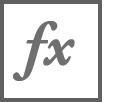`DrawSaturn(opts)`

This function is used throughout the script for all the figure representing the rocket, or part of the rocket. It allows the representation of physical concept such as the control volume, exhaust velocity, etc.

**Example:**

This code would draw Saturn V zoomed-in the bottom surface of the rocket with plotting of the exhaust velocity:

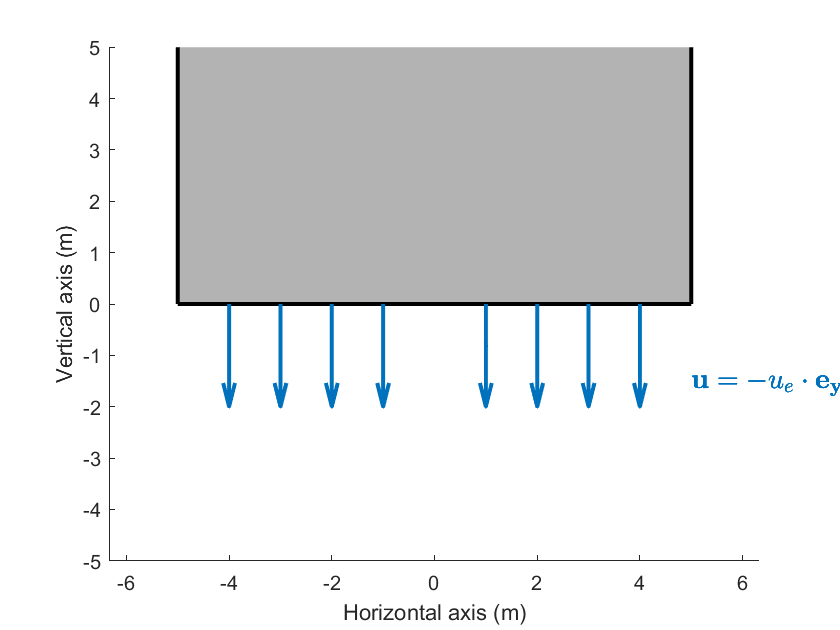

function ax = DrawSaturn(opts)
    arguments
        opts.ControlVolume (1,1) uint8 {mustBeMember(opts.ControlVolume, [0 1 2 3])} = 0 
        opts.DrawFootball (1,1) logical = false
        opts.Highlight (1,1) string {mustBeMember(opts.Highlight, ["none" "CV" "CSR" "CSL" "CSB"])} = "none"
        opts.NormalVector (1,1) logical = false
        opts.Gravity (1,1) logical = false
        opts.ZoomIn (1,1) logical = false
        opts.DrawExhaustVelocity (1,1) logical = false
        opts.DrawExhaustMassFlow (1,1) logical = false
        opts.WriteExhaustVelocity (1,1) logical = false
        opts.WriteExhaustMassFlow (1,1) logical = false
        opts.WriteMass (1,1) logical = false
        opts.DrawThrust (1,1) logical = false
        opts.DrawAcceleration (1,1) logical = false
        opts.PathAngle (1,1) double = 0 % (degree)
        opts.WriteEquation (1,1) string = ""
    end

    % Define the axis:
    f = figure;
    ax = axes(f);
    xlabel(ax,"Horizontal axis (m)")
    ylabel(ax,"Vertical axis (m)")
    axis equal
    ColorHighlight = ax.ColorOrder(3,:);

    % Plot Control Volume background for config A and C:
    if opts.ControlVolume == 1 || opts.ControlVolume == 3
        CV = patch([-40 40 40 -40],[0 0 120 120],ax.ColorOrder(1,:),FaceAlpha=0.2, ...
            LineStyle="none",DisplayName='Control Volume');
        CV.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([-40  40],[120 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([ 40  40],[  0 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
        CS = line([-40 -40],[  0 120],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        CS.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end 
    
    % Define the rocket shape:
    xR = [0 5 5  3.3 3.3 2.0 2.0 1.14 1.14 0.63 0.63  0  ]; % (m) x-position
    yR = [0 0 64 70  82  91  95  98   101  103  110.5 112]; % (m) y-position
    xC = 0.5*(xR(2:end-1)+xR(3:end));
    yC = 0.5*(yR(2:end-1)+yR(3:end));
    nC = [xR(3:end)-xR(2:end-1); yR(3:end)-yR(2:end-1)];
    nC = nC ./ vecnorm(nC);

    % Plot the rocket background:
    if opts.Highlight ~= "CV"
        patch([-xR flip(xR(2:end))],[yR flip(yR(2:end))],[0.7 0.7 0.7], ...
            EdgeColor="none",DisplayName='Saturn V');
    else
        patch([-xR flip(xR(2:end))],[yR flip(yR(2:end))],ColorHighlight, ...
            EdgeColor="none",DisplayName='Saturn V');
    end
    
    
    % Plot right Control Surface:
    CSR = line(xR(2:end),yR(2:end),Color=[0 0 0],LineStyle="-",LineWidth=2);
    CSR.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSR"
        CSR.Color = ColorHighlight;
        CSR.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSR.DisplayName = "Right Control Surface";
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        CSR.Color = ax.ColorOrder(1,:);
        CSR.LineStyle = "--";
    end

    % Plot left Control Surface:
    CSL = line(-xR(2:end),yR(2:end),Color=[0 0 0],LineStyle="-",LineWidth=2, ...
        DisplayName='');
    CSL.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSL"
        CSL.Color = ColorHighlight;
        CSL.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSL.DisplayName = "Left Control Surface";
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        CSL.Color = ax.ColorOrder(1,:);
        CSL.LineStyle = "--";
    end
    

    % Plot bottom Control Surface:
    CSB = line([-xR(2) xR(2)],[yR(2) yR(2)],Color=[0 0 0],LineStyle="-",LineWidth=2);
    CSB.Annotation.LegendInformation.IconDisplayStyle = 'off';
    if opts.Highlight == "CSB"
        CSB.Color = ColorHighlight;
        CSB.Annotation.LegendInformation.IconDisplayStyle = 'on';
        CSB.DisplayName = "Bottom Control Surface";
    elseif opts.ControlVolume == 2
        CSB.Color = ax.ColorOrder(1,:);
        CSB.LineStyle = '--';
    end

    RotZ = @(x) [cosd(x) -sind(x) 0.0;...
                 sind(x)  cosd(x) 0.0;...
                 0.0      0.0     1.0]; 
    % Plot Vector normal:
    if opts.NormalVector && opts.Highlight ~= "none"
        switch (opts.Highlight)
            case "CSR"
                NormalPosition = [xC; yC; 0*yC];
                NormalDirection = 15*RotZ(-90)*[nC(1,:); nC(2,:); 0*nC(2,:)];
            case "CSL"
                NormalPosition = [-xC; yC; 0*yC];
                NormalDirection = 15*RotZ(-90)*[nC(1,:); nC(2,:); 0*nC(2,:)];
                NormalDirection(1,:) = -NormalDirection(1,:); 
            case "CSB"
                if (opts.ZoomIn)
                    NormalPosition = [0 0 0]';
                    NormalDirection = [0 -3 0]';
                else
                    NormalPosition = [0 0 0]';
                    NormalDirection = [0 -20 0]';
                end
        end
        NormalPosition = RotZ(-opts.PathAngle)*NormalPosition;
        NormalDirection = RotZ(-opts.PathAngle)*NormalDirection;
        hold on
        quiver(NormalPosition(1,:),NormalPosition(2,:),NormalDirection(1,:), ...
            NormalDirection(2,:),0,AutoScale="off",LineWidth=2,Color=ColorHighlight, ...
            MaxHeadSize=0.5,DisplayName="$\vec{n}$");
        hold off
    end

    % Draw football field
    if opts.DrawFootball
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1]; % 9.1 meters = 10 yards
        patch(xF,yF,ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5,i*9.1,(i-1)+" 0",Rotation=90,Color="w",HorizontalAlignment="center",FontWeight="bold")
                text(86.5,i*9.1,(11-i)+" 0",Rotation=-90,Color="w",HorizontalAlignment="center",FontWeight="bold")
            end
        end
        yF = yF + 9.1;
        patch(xF,yF,ax.ColorOrder(7,:))
    else
        legend('show', 'location', 'bestoutside', 'Interpreter', 'latex')
    end
    
    % Draw Arrows Out for Exhaust Velocity (requires zoom in bottom)
    if opts.DrawExhaustVelocity && opts.ZoomIn
        hold on 
        x_Ue = [-4:-1 1:4];
        y_Ue = 0*x_Ue;
        u_Ue = 0*x_Ue;
        v_Ue = u_Ue - 2;
        q_Ue = quiver(x_Ue,y_Ue,u_Ue,v_Ue,AutoScale="off",LineWidth=2, ...
            Color=ax.ColorOrder(1,:),MaxHeadSize=0.5,DisplayName="$\vec{u}$");
        if opts.WriteExhaustVelocity
            q_Ue.DisplayName = "$\vec{u} = -u_e\cdot\vec{e_y}$";
        end
    end
    
    % Draw Box out for Exhaust Mass Flow (requires zoom in bottom)
    if opts.DrawExhaustMassFlow && opts.ZoomIn
        p_Me = patch([-5 5 5 -5],[-2 -2 0 0],ax.ColorOrder(1,:),FaceAlpha=0.2,LineStyle="none");
        l_Me = line([-5 -5 5 5],[0 -2 -2 0],Color=ax.ColorOrder(1,:),LineStyle="--",LineWidth=2);
        p_Me.Annotation.LegendInformation.IconDisplayStyle = 'off';
        l_Me.Annotation.LegendInformation.IconDisplayStyle = 'off';
        if opts.WriteExhaustMassFlow
            p_Me.Annotation.LegendInformation.IconDisplayStyle = 'on';
            p_Me.DisplayName = "$\dot{m}_e$";
        end
    end
    
    if opts.PathAngle ~= 0
        l = line([0 0],[-10 130],LineStyle="-.",Color="k");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hl = line([0 0],[0 yR(end)+20],LineStyle="-.",Color="k");
        rotate(hl,[0 0 1],opts.PathAngle,[0 yR(end) 0])
        hl.Annotation.LegendInformation.IconDisplayStyle = 'off';
        i = linspace(0,opts.PathAngle, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        p = plot(x,y,"k-");
        p.Annotation.LegendInformation.IconDisplayStyle = 'off';
        hold off
        text(mean(x),mean(y)-4,"$\alpha$",Interpreter="latex",FontSize=14)    
        child = allchild(ax);
        rotate(child,[0 0 1],-opts.PathAngle,[0 0 0])
    end

    if opts.WriteMass
        text(0, 2.5,"$m(t)$",Interpreter="latex",HorizontalAlignment="center",FontSize=14)
    end
   
    if opts.DrawThrust
        xPos = [0 0];
        if opts.ZoomIn
            xDir = [0 2];
        else
            xDir = [0 20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2,...
            Color=ax.ColorOrder(7,:),MaxHeadSize=0.5,DisplayName="$\vec{F}_{Thrust}$")
        hold off
    end

    if opts.DrawAcceleration
        xPos = [0 0];
        if opts.ZoomIn
            xDir = [0 -3];
        else
            xDir = [0 -20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2, ...
            Color=ax.ColorOrder(5,:),MaxHeadSize=0.5,DisplayName="$\vec{F}_{Acceleration}$");
        hold off
    end

    if opts.Gravity
        xPos = [2 4];
        if opts.ZoomIn
            xDir = [0 -3];
        else
            xDir = [0 -20];
        end
        hold on
        quiver(xPos(1),xPos(2),xDir(1),xDir(2),0,AutoScale="off",LineWidth=2, ...
            Color="k",MaxHeadSize=0.5,DisplayName="$\vec{g}$");
        hold off
    end

    if opts.ControlVolume == 1
        l = line([ 5  40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
        l = line([-5 -40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
    if opts.ControlVolume == 3
        l = line([-40 40],[0 0],Color=ax.ColorOrder(1,:),LineWidth=2,LineStyle="--");
        l.Annotation.LegendInformation.IconDisplayStyle = 'off';
    end
    
    % change the plotting limit if zooming onto the bottom of the rocket:
    if opts.ZoomIn
        ylim([-5 5])
    end
end

###   **Try** Function

`LookAtNormalVector(str)`

Explore the concept of normal unit vector along the different control surfaces. The input string `str` is refering to the right control surface `"CSR"`, the left control surface `"CSL"`, the bottom control surface `"CSB"`.

**Example:**

This code would draw Saturn V zoomed-in the bottom surface of the rocket with plotting of the exhaust velocity.

function LookAtNormalVector(str)
    arguments
        str (1,1) string {mustBeMember(str,["none" "CSR" "CSL" "CSB"])} = "none"
    end
    DrawSaturn(Highlight=str, NormalVector=true);
    title("Normal Unit Vector")
end

⇦ Return to function uses in the script

**SolveMassConservationEquation(me)**

Solves the differential equation arising from the mass conservation equation, with `me` the mass flow rate (kg/s) at the rocket engine exhaust.

**Example:**

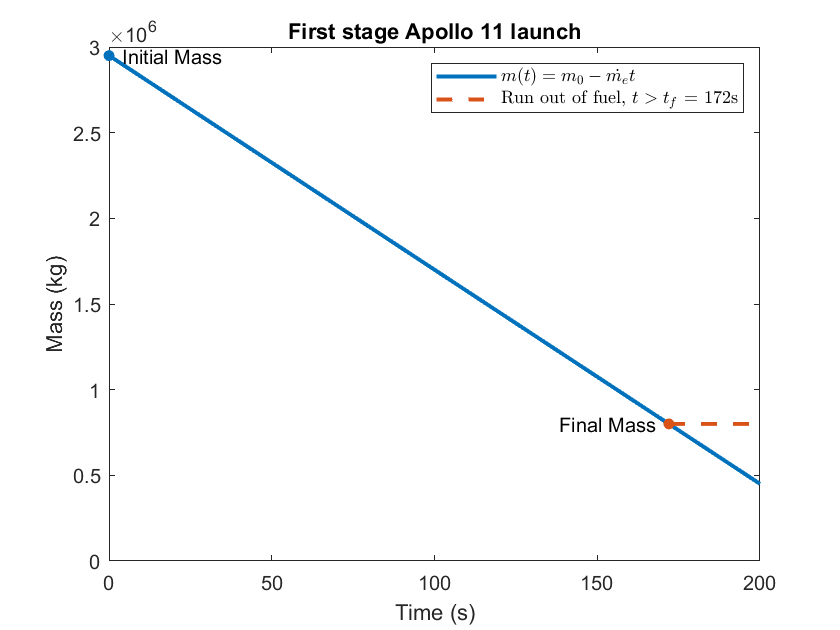

function SolveMassConservationEquation(me)
    arguments
        me (1,1) double  {mustBeGreaterThan(me,0)}
    end

    % Problem parameters:
    m0 = 2950000; % Initial mass of the rocket (kg)
    mp = 2000000; % Mass propellant (kg)
    mf = m0 - mp; % Final mass of the rocket (kg)
    tf = mp/me;   % Final time rocket first stage burnout (s)
    
    % Define differential equation from mass cons. eq.:
    m = @(t) m0 - me*t; % mass rocket (kg) w.r.t. time valid for t = [0 tf]

    % Plot results:
    figure
    pt = [0 200]; % Time plotting window (s)
    t = linspace(0,tf,2); % Time (s)
    plot(t,m(t),SeriesIndex=1,LineWidth=2)
    hold on
    scatter(0,m0,30,"filled",SeriesIndex=1)
    text(0,m0,"  Initial Mass")
    scatter(tf,mf,30,"filled",SeriesIndex=1)
    text(tf,mf,newline+"  Final Mass")
    if tf < pt(2)
        plot([tf 200],[mf mf],SeriesIndex=1,LineWidth=2,LineStyle="--")
        scatter(tf,mf,30,"filled",SeriesIndex=1)
    end
    hold off

    xlabel("Time (s)")
    ylabel("Mass (kg)")
    xlim([0 200])
    ylim([0 3000000])
    title("Rocket mass during launch first phase")
end

⇦ Return to function uses in the script

**SolveMomentum(me, gravity, angle)**

Solves the differential equation arising from the momentum conservation equation (considering the results from the mass conservation equation). With `me` the mass flow rate (kg/s) at the rocket engine exhaust; `gravity` a boolean that is `true` if gravity is considered variable with altitude, `false` otherwise; `angle` is a boolean that is `true` if the path of the rocket flight path angle is taken into consideration, `false` otherwise.

**Example:**

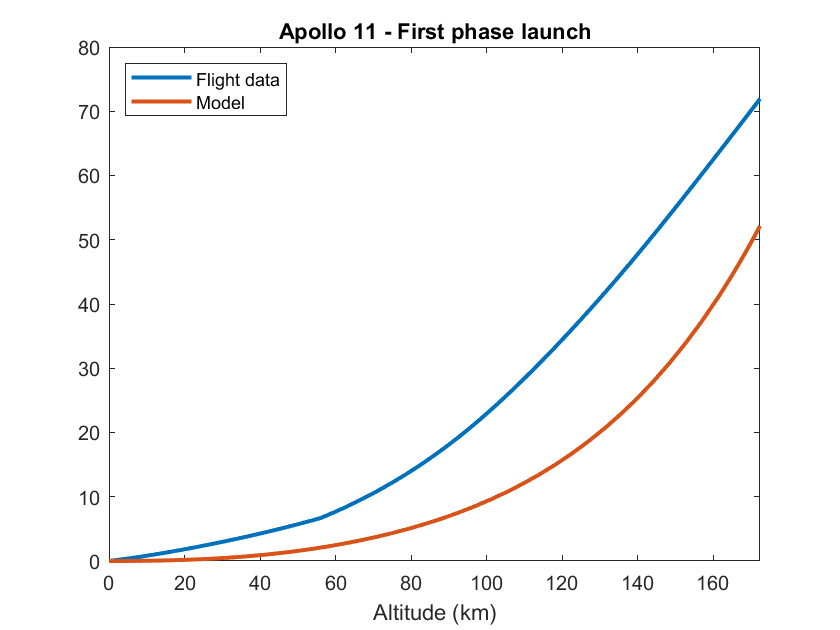

function SolveMomentum(me,gravity,angle)
    arguments 
        me (1,1) double
        gravity (1,1) logical = 0
        angle (1,1) logical = 0
    end
    
    % Define earth gravity:
    m_earth = 5.9722e+24; % Earth's mass (kg)
    r_earth = 6371.0e+3 ; % Earth's radius (m)
    G = 6.6743e-11; % Gravitational constant (m3.kg-1.s-2)   
    if gravity
        g = @(y) G*m_earth./(r_earth+y).^2;
    else
        g = @(y) G*m_earth/r_earth^2;
    end

    % Define flight path angle:
    if angle
        load Apollo11.mat FirstPhase
        alpha = @(t) interp1(FirstPhase.t, FirstPhase.Alpha, t, "pchip");
    else
        alpha = @(t) 0;
    end

    % Problem parameters:
    Isp = 282.5; % Specific impulse first stage rocket (s)
                 % Averaged from sea-level specific impule Isp = 261 s
                 % And vaccum specific impulse Isp = 304 s
    ue = g(0)*Isp; % Exhaust velocity of the rocket engine (m.s-1)
                   % gravity considered for exhaust velocity is taken at
                   % sea-level, variation with elevation being negligible 
                   % during the first phase of the launch
    m0 = 2950000; % Initial mass of the rocket (kg)
    mp = 2000000; % Mass propellant (kg)
    tf = mp/me;   % Final time rocket first stage burnout (s)
    
    % Results from the mass cons. eq.:
    m = @(t) m0 - me*t; % Mass of the rocket w.r.t time, valid from t = [0 tf];

    % Define the differential equation resulting from momentum cons. eq.:
    ddydt = @(t,y) cosd(alpha(t)).*ue*me./m(t)-g(y);
    dfun = @(t,y) [y(2); ddydt(t,y(1))];
    
    % Solve the differential equation:
    [t,y] = ode45(dfun, [0 tf], [0; 0]);

    % Retrieve results:
    Elevation = y(:,1);
    
    % Plot the results:
    figure
    load Apollo11.mat FirstPhase
    plot(FirstPhase.t, FirstPhase.Altitude/1000, LineWidth=2)
    hold on
    plot(t, Elevation*1e-3, LineWidth=2)
    hold off
    xlim([0 tf])
    str = "Apollo 11 Flight log vs. Model";
    if gravity
        str = str + " with varying gravity";
    end
    if angle
        str = str + " with real flight path";
    end
    title(str)
    legend("Flight log", "Model", Location="northwest")
    xlabel("Elevation (km)")
end

⇦ Return to function uses in the script

`ShowRocketPath()`

Function dsplaying the Apollo 11 flight from lift-off to the intralunar injection when the spacecraft left earth's orbit.

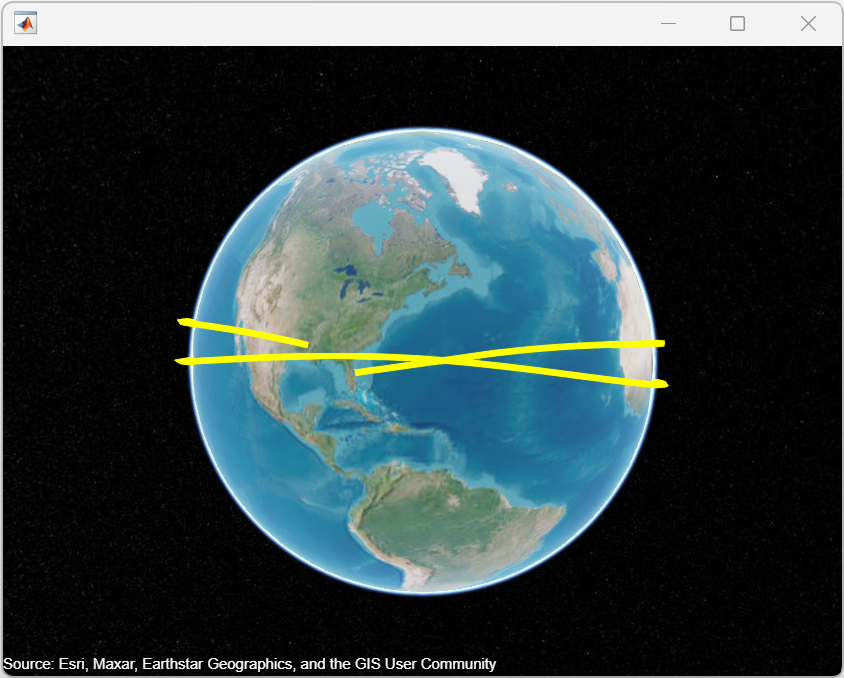

function ShowRocketPath
    load Apollo11.mat Launch
    uif = uifigure;
    g = geoglobe(uif);
    geoplot3(g,Launch.Lat,Launch.Lon,Launch.El,'y','HeightReference','terrain', 'LineWidth',3)
end

⇦ Return to function uses in the script

###  **Exercise** functions

`qControlVolumeDefinition(str)`

function qControlVolumeDefinition( str )
    arguments
        str (1,1) string { mustBeMember(str, ["None", "First", "Second", "Third"]) } = "None"
    end
    
    switch (str)
        case "None"
            warning("Please, select one of the three proposed Control Volume definitions.")
        case "First"
            warning("While selecting the air around the rocket might sound like a good idea," + ...
                " the flow in the area is hard to characterize. Moreover, the rocket is" + ...
                " propelled by the mass flow at the rocket engine exhaust. This definition "+ ...
                "of the Control Volume would not allow to consider this.")
        case "Second"
            disp("Good job! In this case, it makes the most sense to define the Control" + ...
                "Volume as the rocket itself.")
        case "Third"
            warning("Considering the rocket and the air flow around is a good idea, " + ...
                "however the flow in the area surounding the rocket is hard to characterize." + ...
                " Therefore, it might be compelling to exclude this area from the Control Volume.")
    end

end

⇦ Return to function uses in the script

`qNormalBottomSurface(str)`

function qNormalBottomSurface(str)
    arguments
        str (1,1) string {mustBeMember(str,["none" "Sideways" "Upward" "Downward"])} = "none"
    end


    switch (str)
        case "none"
            DrawSaturn(ZoomIn=true,Highlight="CSB");
            warning("Please select either Sideways, Upward or Downward")
        case "Sideways"
            DrawSaturn(ZoomIn=true,Highlight="CSB");
            warning("Because the surface is horizontal, the normal vector to "+ ...
                "the surface is necessarly vertical")
        case "Upward"
            DrawSaturn(ZoomIn=true,Highlight="CSB");
            hold on
            q = quiver(0,0,0,3,0,AutoScale="off",MaxHeadSize=0.5,LineWidth=2,SeriesIndex=3);
            q.Annotation.LegendInformation.IconDisplayStyle = 'off';
            hold off
            warning("Remember that, by convention, the normal vector is defined as going "+...
                "outward from the control volume, so it can not be upward")
        case "Downward"
            DrawSaturn(ZoomIn=true,Highlight="CSB",NormalVector=true);
            disp("Good job! Remember that, by convention, the normal vector is defined"+...
                " as going outward from the control volume.");
    end

    title("Control volume around the bottom of rocket")
end

⇦ Return to function uses in the script

`qNullTermMass(opts)`

function qNullTermMass(opts)
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ( ~opts.A && ~opts.B && ~opts.C && ~opts.D)
        warning("Please, select your answer(s)")
    else
        
        if ( opts.A )
            warning("The mass of the rocket decreases during the launch,"+ ...
                " therefor term A can not be equal to zero.")
        end
        if (~opts.B)
            warning("The right control surface represent part of the hull of the rocket," + ...
                " therefore tarm B has to be equal to zero. There is no possible mass flux " + ...
                "through a wall.")
        end
        if (~opts.C)
            warning("The left control surface represent part of the hull of the rocket," + ...
                " therefore tarm B has to be equal to zero. There is no possible mass flux " + ...
                "through a wall.")
        end
        if ( opts.D )
            warning("The propellant is exiting the rocket from the bottom surface control,"+...
                " therefore there is mass flux through this control surface, and term D can "+ ...
                "not be equal to zero.")
        end
        
        if (~opts.A && opts.B && opts.C && ~opts.D)
            disp("Good job! You indentified all of the null term in the mass conservation equation.")
        end

    end
end

⇦ Return to function uses in the script

`qInertiaMass(int)`

function qInertiaMass(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2 3 4])} = 0
    end
    switch (int)
        case 0
            warning("Please select one of the possible answers.")
        case 1
            disp("Good job! This answer is correct.")
        case 2
            warning("The velocity plays no part in this integral, also the unit of this results is "+...
                "not consistent with unit of mass per unit of time.")
        case 3
            warning("The velocity plays no part in this integral, also the unit of this results is "+...
                "not consistent with unit of mass per unit of time.")
        case 4
            warning("The unit of this answer are not constant with the expected results that should be "+...
                "expressed in term of unit of mass per unit of time.")
    end
end

⇦ Return to function uses in the script

`qDotProductMass(int)`

function qDotProductMass(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2])} = 0
    end
    
    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("The direction of the two vectors involved in the dot product are similar, " +...
                "therefore the results of the dot product should be positive.")
        case 2
            disp("Good job! The vectors are in the same direction so the dot product is positive.")
    end

end

⇦ Return to function uses in the script

`qMassFlowTerm(int)`

function qMassFlowTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2 3])} = 0
    end
    switch int
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("Every remaining term in the integral are scalar,"+ ...
                " therefore the results must be a scalar.")
        case 2
            warning("Every remaining term in the integral are positive,"+...
                " therefore the results from the integral must be positive.")
        case 3
            disp("Good job! The remaining term in the mass conservation equation represent"+ ...
                newline +" the mass flow leaving the control volume through the bottom Control Surface.")
    end


end

⇦ Return to function uses in the script

`qNullTermMomentum(opts)`

function qNullTermMomentum(opts)
    arguments
        opts.CSR (1,1) logical
        opts.CSL (1,1) logical
        opts.CSB (1,1) logical
    end
    
    if ( ~opts.CSR && ~opts.CSL && ~opts.CSB )
        warning("Please, select your answer(s)")
    else
        if ~opts.CSR
            warning("The right control surface is over part of the hull of the rocket, threfore "+...
                "it is equivalent to a wall and mass flux can not go through walls.")
        end
    
        if ~opts.CSL
            warning("The left control surface is over part of the hull of the rocket, threfore "+...
                "it is equivalent to a wall and mass flux can not go through walls.")
        end
    
        if opts.CSB
            warning("There is a flux of propellant throught the botton control surface, " + ...
                "therefore the integral can not be equal to zero.")
        end
        
        if opts.CSR && opts.CSL && ~opts.CSB
            disp("Good job! You found all of the term equal to zero.")
        end
    end
end

⇦ Return to function uses in the script

`qThrustDirection(str)`

function qThrustDirection(str)
    arguments
        str (1,1) string {mustBeMember(str,["None" "Sideways" "Upward" "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("The fow through the rocket engine can not generate thrust that would be sideways."+...
                " It necessarly has be to be normal to the bottom control surface.")
        case "Upward"
            DrawSaturn(ZoomIn=true,Highlight="CSB",NormalVector=true,DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true,WriteExhaustVelocity=true,WriteExhaustMassFlow=true, ...
                WriteMass=true,DrawThrust=true,DrawAcceleration=false);
            title("Rocket with Thrust force")
        case "Downward"
            warning("Newton's third law of motion states that to every actions there is always an opposed " + ...
                "equal reaction. The action in our case is the mass flow going downward, so the reaction " + ...
                "can not be downard.")
    end
end

⇦ Return to function uses in the script

`qThrustSign(int)`

function qThrustSign(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2])} = 0
    end
    
    switch int
        case 0
            warning("Please select either negative or positive.")
        case 1
            warning("Careful about the sign resulting product.")
        case 2
            disp("Good job!")
    end
end

⇦ Return to function uses in the script

`qThrustTerm(str)`

function qThrustTerm(str)
    arguments
        str (1,1) string {mustBeMember(str,["None" "A" "B" "C" "D"])}
    end
    
    switch (str)
        case "None"
            warning("Please select A, B, C or D.")
        case "A"
            warning("Remember that according to the previous question the results of the integral" + ...
                "should be negative. Moreover, the unit of the results should be unit of mass" + ...
                " times unit of length per unit of time square.")
        case "B"
            DrawSaturn(...
            ZoomIn=true,...
            Highlight="CSB",...
            NormalVector=true,...
            DrawExhaustVelocity=true,...
            DrawExhaustMassFlow=true,...
            WriteExhaustMassFlow=true,...
            WriteExhaustVelocity=true);
            expr = "$\displaystyle \int_{CSB} (\vec{u}\cdot\vec{n})\rho(\vec{u}\cdot\vec{e_y}\;dS) = -u_e\dot{m}_e$";
            title(expr, Interpreter="latex")
        case "C"
            warning("The unit of the results should be unit of mass" + ...
                " times unit of length per unit of time square.")
        case "D"
            warning("The unit of the results should be unit of mass" + ...
                " times unit of length per unit of time square.")
    end

end

⇦ Return to function uses in the script

`qBodyForces(opts)`

function qBodyForces(opts)
    arguments 
        opts.Gravity (1,1) logical
        opts.Spring (1,1) logical
        opts.Electric (1,1) logical
        opts.Friction (1,1) logical
        opts.Magnetic (1,1) logical
        opts.Thrust (1,1) logical 
        opts.Acceleration (1,1) logical
    end

    if ( ~opts.Gravity && ~opts.Spring && ~opts.Electric && ~opts.Friction && ...
            ~opts.Magnetic && ~opts.Thrust && ~opts.Acceleration)
        warning("Please select your answer(s)")
    else

        if (~opts.Gravity)
            warning("While gravity could be neglected for a spacecraft flying in deep space, it is necessary " + ...
                "to include it for the first phase of Saturn V launch.")
        end
    
        if (opts.Spring)
            warning("The rocket is not connected to any spring, therfore there is no spring force.")
        end
    
        if (opts.Electric)
            warning("Saturn V is not subject to any electric field.")
        end
    
        if (~opts.Friction)
            warning("Even tough the atmosphere quickly become less dense with altitude, the air surrounding the " + ...
                "rocket is resisting the rocket.")
        end
    
        if (opts.Magnetic)
            warning("Saturn V is not subject to a magnetic field strong enough to impact is trajectory.")
        end
    
        if (opts.Thrust)
            warning("The thrust acting on the rocket do not need to be model as external forces, as it " + ...
                "is already model by the integral thrust term that we calculated in the previous subsection.")
        end
    
        if (~opts.Acceleration)
            warning("The control volume being in constant acceleration during the first phase of the lanch, "+ ...
                "we are modelling the effect of this acceleration as a force acting on the control volume.")
        end
    
        if (opts.Gravity && ~opts.Spring && ~opts.Electric && ...
            opts.Friction && ~opts.Magnetic && ~opts.Thrust && ...
            opts.Acceleration )
            disp("Good Job! You identified all the right body forces for this problem.")
        end

    end

end

⇦ Return to function uses in the script

`qGravityTerm(int)`

function qGravityTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2 3 4])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answers.")
        case 1
            warning("The gravity force is function of the mass of the control volume, not its initial " + ...
                "mass. Moreover, because gravity is directed downward, its mathematical expression in " + ...
                "our reference frame should be negative.")
        case 2
            warning("The gravity force is function of the mass of the control volume, not its initial mass.")
        case 3
            warning("The gravity force is function of the mass of the control volume, not the mass flow " + ...
                "through the rocket engine.")
        case 4
            disp("Good job!")
    end
end

⇦ Return to function uses in the script

`qAccelerationDirection(str)`

function qAccelerationDirection(str)
    arguments
        str (1,1) string {mustBeMember(str,["None" "Sideways" "Upward" "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("Wrong, the resulting thrust is parallel to the exhaust velocity! Try Again!")
        case "Upward"
            warning("Wrong, the force due to the acceleration of the control volume is in opposite"+...
                " direction of the acceleration. Just like we experience an force pushing us"+...
                " forward while using the break in a car.")
        case "Downward"
            disp("Good job! Resulting forces are always directed in the opposite direction of their sources.")
            DrawSaturn(...
                ZoomIn=true,...
                Highlight="CSB",...
                NormalVector=true,...
                DrawExhaustVelocity=true,...
                DrawExhaustMassFlow=true,...
                WriteExhaustVelocity=true,...
                WriteExhaustMassFlow=true, ...
                WriteMass=true,...
                DrawAcceleration=true);
    end
    % XXX Add more feedback
end

⇦ Return to function uses in the script

`qAccelerationTerm(int)`

function qAccelerationTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2 3 4])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("The acceleration force is oriented downard, therefore its mathematical expression" + ...
                "within the reference frame that we defined should be negative.")
        case 2
            disp("Good job!")
        case 3
            warning("The acceleration force is oriented downard, therefore its mathematical expression" + ...
                "within the reference frame that we defined should be negative. Moreover, this term " + ...
                "should be function of the mass of the control volume, not the mass flow.")
        case 4
            warning("this term should be function of the mass of the control volume, not the mass flow.");
    end

end

⇦ Return to function uses in the script

`qSourceInaccuracy(opts)`

function qSourceInaccuracy(opts)
    arguments
        opts.BadPhysics (1,1) logical
        opts.Friction (1,1) logical
        opts.FlightPath (1,1) logical
        opts.Gravity (1,1) logical
        opts.Performance (1,1) logical
    end

    if ( ~opts.BadPhysics && ~opts.Friction && ~opts.FlightPath && ...
            ~opts.Gravity && ~opts.Performance )
        
        warning("Please select your answer(s)")
    
    else

        if (opts.BadPhysics)
            warning("")
        end
    
        if (~opts.Friction)
            warning("You are forgetting that so far we have been neglecting the force from the" + ...
                "air resistance.")
        end
    
        if (~opts.FlightPath)
            warning("You are forgetting that so far we have been neglecting the real trajectory " + ...
                "of the rocket.")
        end
    
        if (~opts.Gravity)
            warning("Gravity is decreasing with altitude, considering it constant is a cause of innacuracy.")
        end
    
        if (~opts.Performance)
            warning("Remember that so far we have been considering the rocket engines performance to be" + ...
                " constant during the first phase of the flight.")
        end
    
        if (~opts.BadPhysics && opts.Friction && opts.FlightPath && ...
             opts.Gravity && opts.Performance)
            disp("Good job!")
        end

    end

end

⇦ Return to function uses in the script

`qTrigFunction(int)`

function qTrigFunction(int)
    arguments
        int (1,1) uint8 {mustBeMember(int,[0 1 2 3 4])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("The velocity vector is align with the rocket axis, be careful with your projection.")
        case 2
            warning("The velocity vector is align with the rocket axis, be careful with your projection.")
        case 3
            disp("Good job!")
        case 4
            warning("The velocity vector is align with the rocket axis, be careful with your projection.")
    end

    load Apollo11.mat FirstPhase
    figure
    plot(FirstPhase.t,FirstPhase.Alpha,LineWidth=2)
    xlabel("Time (s)")
    ylabel("Path Angle (\circ)")
    title("Apollo 11 Flight log - Trajectory")

end

⇦ Return to function uses in the script

[⇦ Return to the navigation page](matlab: OpenOverview)